# **Exercici 3. **

Es pretén dissenyar un algoritme simple d’auto-enfoc. La idea és comparar varies imatges d’una mateixa escena adquirides movent l’enfoc de la càmera (que se suposa motoritzat).  Per exemple en la següent seqüència d’imatges es pot veure com al anar variant la distància focal de la lent s’obtenen imatges amb enfoc en diferents profunditats. Les imatges les trobareu annexes a aquest document.

Com es pot observar, quant una part de la imatge està desenfocada presenta els contorns suavitzats. Llavors, la idea bàsica del nostre senzill sistema d’auto-enfoc és que la imatge que contingui més “derivada” en la seva part central és que estarà més ben enfocada. 

- El primer que farem és llegir les imatges i les convertim a nivell de grisos (rgb2gray).

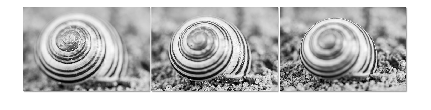

CLOSE = rgb2gray(imread('_61A5845.jpg'));
MID = rgb2gray(imread('_61A5855.jpg'));
FAR = rgb2gray(imread('_61A5861.jpg'));

montage([CLOSE,MID,FAR]);      

2. Passarem un filtre derivatiu (*sobel* o similar) per detectar els contorns verticals Sy i horitzontals Sx. Vigileu el tipus de la imatge doncs no us trunqui els valors negatius o valors més grans que 255.

3. Com que en aquesta aplicació és indiferent si el contorn és positiu o negatiu, vertical o horitzontal, calcularem el valor absolut de Sx i Sy, i els sumarem.

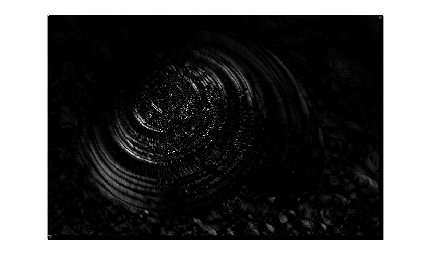

h = fspecial('sobel');
vCLOSE = imfilter(CLOSE,h);         %%hortizontal
hCLOSE = imfilter(CLOSE,h');        %%vertical

sumaCLOSE = imfilter(CLOSE, h+h');

absCLOSE = abs(vCLOSE) + abs(hCLOSE);
%montage([cCLOSE,composedCLOSE]);
imshow(absCLOSE-sumaCLOSE);

En un principi haviem escollit com a matriu h+h', pro hem vist que a la suma dels valors absoluts hi ha molt mes detall, per tant seguirem amb aquesta segona opció.

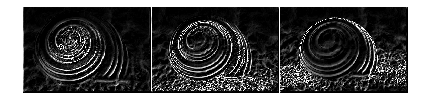

absMID   = abs(imfilter(MID,h)) + abs(imfilter(MID,h'));
absFAR   = abs(imfilter(FAR,h)) + abs(imfilter(FAR,h'));
montage([absCLOSE,absMID,absFAR]);

        4. Calcularem un valor ***m***de mèrit de l’enfoc i compararem els resultats de les tres imatges. La imatge que proporcioni un valor ***m*** més alt és la que es considerarà de millor enfoc. La funció que calcula el valor ***m*** queda a la vostre elecció, però seria interessant que ponderes amb major pes els píxels centrals de la imatge que els de la perifèria.  

merit1(absCLOSE)

ans = 10.6180

merit1(absMID)

ans = 16.0197

merit1(absFAR)

ans = 13.7806

***function [y] = merit1(X)***

*[f c] = size(X);*

*y = (sum(sum(X))*100)/(f*c*255);*

***end***

Amb aquesta primera funció nomes mirem quina de les imatges te els contorns més definits en general, és a dir la que te una area total enfocada major, sense tenir en compte on esta l'area situada a l'imatge. En aquest cas guanya la segona foto.

merit2(absCLOSE)

ans = 2.7171e+10

merit2(absMID)

ans = 3.1851e+10

merit2(absFAR)

ans = 2.2715e+10

***function [r] = merit2(q)***

*p = cast(q,'double');*

*[f c] = size(p);*

*const = mod(f,2);*

*x = [linspace(0,100,(f/2)+const) flip(linspace(0,100,f/2))];*

*const = mod(c,2);*

*y = [linspace(0,100,(c/2)+const) flip(linspace(0,100,c/2))];*

*mat = (x' * y);*

*r = sum(sum(p .* mat));*

***end***

*Amb aquesta segona funció hem definit una matriu on els valors que son més al centre son progressivament més grans. En aquest cas també tenim que la fotografia amb més puntuació es la segona, però ara la segona amb més puntuació és la primera, el que té sentit ja que les valors més grans del filtre estan situats al mitg.*

merit3(absCLOSE)

ans = 1004063

merit3(absMID)

ans = 695221

merit3(absFAR)

ans = 326967

***function [y] = merit3(x)***

*[f c] = size(x);*

*f4 = ceil(f/8);*

*c4 = ceil(c/8);*

*Mitj = x(3*f4:5*f4,3*c4:5*c4);*

*y = sum(sum(Mitj));*

***end***

Per ultim, en aquesta tercera funció  només tenim en compte la part central de la imatge, i com era d'esperar l'imatge amb la puntuació més alta es la del focus mes proper.

Proveu el vostre algoritme amb altres imatges. Justificar amb histogrames o gràfiques l'elecció dels llindars. Feu un informe raonat, pas a pas, amb el que heu fet i entregueu-lo a Atenea.  

#        TESTEO

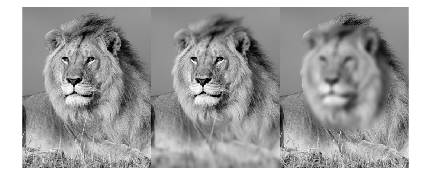

leonOG = rgb2gray(imread('leon.png'));
leonCara = rgb2gray(imread('leon2.png'));
leonCuerpo = rgb2gray(imread('leon3.jpg'));


montage([leonOG,leonCara,leonCuerpo]); 

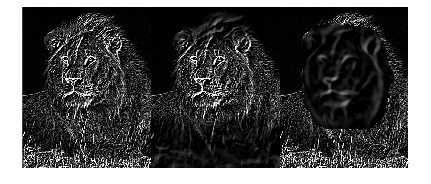

absLeonOG = abs(imfilter(leonOG,h)) + abs(imfilter(leonOG,h'));
absLeonCara = abs(imfilter(leonCara,h)) + abs(imfilter(leonCara,h'));
absLeonCuerpo = abs(imfilter(leonCuerpo,h)) + abs(imfilter(leonCuerpo,h'));
montage([absLeonOG,absLeonCara,absLeonCuerpo]);

merit1(absLeonOG)

ans = 17.5143

merit1(absLeonCara)

ans = 11.8054

merit1(absLeonCuerpo)

ans = 11.4338

merit2(absLeonOG)

ans = 2.1696e+10

merit2(absLeonCara)

ans = 1.8553e+10

merit2(absLeonCuerpo)

ans = 9.2604e+09

merit3(absLeonOG)

ans = 757174

merit3(absLeonCara)

ans = 770045

merit3(absLeonCuerpo)

ans = 253667

*Els resultats amb aquest set de proves que hem creat donen els mateixos resultats que haviem obtingut abans.*